# Interface Métodos Numéricos para ED/PVI

**28/03/2022     Arménio Correia     armenioc@isec.pt**

## 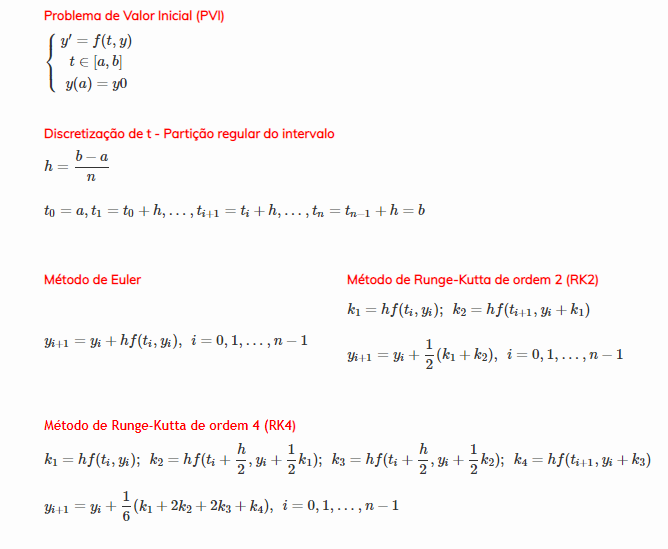

clear
syms y(t)

while 1
    strF = "y+exp(3*t)";
    f =@(t,y) eval(vectorize(strF));
    try
        z = f(t,y);
        break
    catch ME
        waitfor(errordlg("Introduza uma função em t e y","Erro")) 
    end
end

while 1
    a = 1;
    if (isscalar(a) && isreal(a)) 
        break
    end
end

while 1
    b = 1.5;
    if (isscalar(b) && isreal(b) && b>a) 
        break
    else 
        waitfor(errordlg("Introduza um b > a","Erro")); 
    end
end

n = 2;
y0 = 2;

sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
g =@(t) eval(vectorize(char(sExata)));

[t,yEuler] = NEuler(f,a,b,n,y0);
[~,yRK2] = NRK2(f,a,b,n,y0);

yExata = g(t);
erroEuler = abs(yExata-yEuler);
erroRK2 = abs(yExata-yRK2);

matrizResultados = [t.', yExata.', yEuler.',yRK2.',erroEuler.',erroRK2.'];
tabelaResultados = array2table(matrizResultados,...
    "VariableNames",["t","Exata","Euler","RK2","erroEuler","erroRK2"])

tabelaResultados = 3×6 table
     t      Exata     Euler      RK2      erroEuler      erroRK2  
    ____    ______    ______    ______    __________    __________

       1         2         2         2    1.7764e-15    1.7764e-15
    1.25    10.933    7.5214    11.016         3.412      0.082579
     1.5    31.748    20.032     32.01        11.716       0.26203


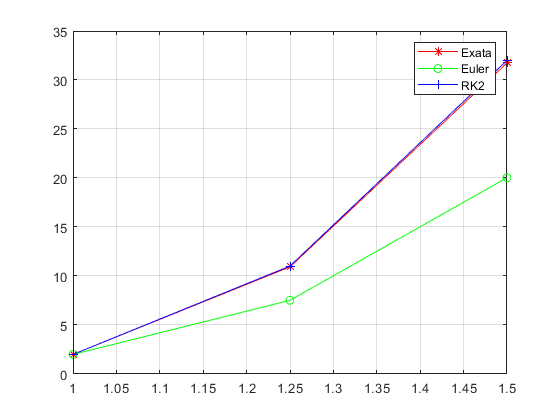


plot(t,yExata,"-*r")
hold on
plot(t,yEuler,"-og")
plot(t,yRK2,"-+b")
hold off
grid on
legend("Exata","Euler","RK2")